### SVM на спектре

clear all
close all
path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

NOTES = 84;

Параметры для изменений

NFFT = 1024;            % Кол-во отчетов для вырезки
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
N_row = N;
ds = 11;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

Заполняю X и Y

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей
data = data(:, 1:87);       % Откидываем 5тую октаву ноту До
data = data(:,4:end);       % Откидываю первые 3 ноты суб-контр октавы

Y = zeros(N_row*NOTES, 1);
X = zeros([N_row*NOTES, NFFT+N_zero]);  % С Интерполяцией
% X = zeros([N_row*NOTES, NFFT]);       % Без интерполяции

for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),NFFT,[])';
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% OPTIONAL
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Window function
    % Add Hamming window
    h = hamming(NFFT)';
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end


cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear z X Y y

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

% Normalization of data
XTest_ds  = XTest_ds ./ max(XTest_ds, [], 2);   %sum(XTest_ds, 2);
XTrain_ds = XTrain_ds ./ max(XTrain_ds, [], 2); %sum(XTrain_ds, 2);

clear XTrain XTest XTest_spec XTrain_spec

tic
Mdl_freq = fitcecoc(XTrain_ds,YTrain);
class(Mdl_freq)

ans = 'cell'

toc

Elapsed time is 245.979453 seconds.


tic
label = predict(Mdl_freq,XTest_ds);
toc

Elapsed time is 88.201453 seconds.


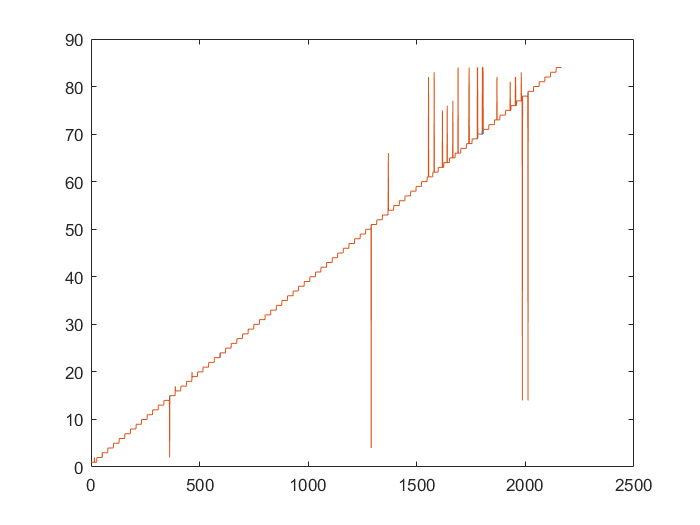


figure
plot(YTest)
hold on
plot(label)

%title('SVM Using spectrum')


errors = zeros([STest, 1]);
for i = 1:STest
    if YTest(i) ~= label(i)
        errors(i) = 1;
    end
end
errors = 100 * sum(errors)/STest

errors = 1.4305

### SVM using Ms matrix

clear all
close all

path = "D:\Desktop\Studie\Diploma\GIT Matlab\Audio data\wav";
path1 = path + "\Sasha\Steinway Grand Piano 70.wav";
[y, Fs] = audioread(path1);
z = y(:,1);

NOTES = 84;

Tab_F_1 = [65.41  69.3  73.42  77.78  82.41  87.31  92.5  98  103.83  110  116.54  123.47];
k = 2.^(0:6) / 2;
Tab_F = k' .* repmat(Tab_F_1, 7, 1);

M = zeros(7, 12);
Ms = M;

Изменяемые параметры

NFFT = 1024;
N_zero = Fs - NFFT;     % Кол-во нулей после вырезки. Я буде для частотного шага 1Гц
N = floor(2/(NFFT/Fs)); % Количество вырезок за 2 секунды
ds = 11;                % В сколько раз уменьшить спектр. Минимум 2 - нормально

Получаю отдельные колонки для отдельных нот

data = reshape(z,4*Fs,[]);  % Каждая нота отдельно
data = data(1:N*NFFT, :);   % Каждая нота отдельно Без нулей
data = data(:, 1:87);       % Откидываем 5тую октаву ноту До
data = data(:,4:end);       % Откидываю первые 3 ноты суб-контр октавы

Заполняю Х и У с вырезками нот длинной в NFFT

Y = zeros(N*NOTES, 1);
X = zeros([N*NOTES, NFFT+N_zero]);    % С интерполяцией
% X = zeros([N*NOTES, NFFT]);             % Без интерполяции

for k=1:NOTES
    
    N1 = N * (k-1) + 1;
    N2 = N1 + N - 1;
    
    notes = reshape(data(:,k),NFFT,[])';
    
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% OPTIONAL
    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Window function
    % Add Hamming window
    h = hamming(NFFT)';
    notes = notes .* h;
    
    X(N1:N2, 1:NFFT) = notes;
    Y(N1:N2) = k;
    
end

Разделяю данные на тестовые и тренировочные

cv = cvpartition(Y,'HoldOut',0.30);
trainInds = training(cv);
testInds = test(cv);

XTrain = X(trainInds,:);
YTrain = Y(trainInds);
XTest = X(testInds,:);
YTest = Y(testInds);

clear X z

Нахожу спектры этих данных и урезаю их (беру 1/ds от спектра). А так же нормализирую спектры

[STest, MTest] = size(XTest);
[STrain, MTrain] = size(XTrain);

Ms_Train = zeros(STrain, 7, 12); %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
Ms_Test = zeros(STest, 7, 12);%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

vtest = floor(1:MTest/ds);
vtrain = floor(1:MTrain/ds);

XTest_ds = zeros([STest, length(vtest)]);
XTrain_ds = zeros([STrain, length(vtrain)]);

% Get Spectrum. There is no need to get whole spectrum, It can be divided
% by half or more. ds - specifies how spectrum will be divided.
XTest_spec = abs(fft(XTest'))';
XTrain_spec = abs(fft(XTrain'))';

% Get only one part of spectrum, only important samples
XTest_ds(:, vtest) = XTest_spec(:, vtest);
XTrain_ds(:, vtest) = XTrain_spec(:, vtest);

% Normalization of data
XTest_ds  = XTest_ds ./ max(XTest_ds, [], 2);   %sum(XTest_ds, 2);
XTrain_ds = XTrain_ds ./ max(XTrain_ds, [], 2); %sum(XTrain_ds, 2);

clear XTest XTrain

Нахожу тренировочные Ms матрицы

Indexes = floor(Tab_F);   % NOT FLAT!!!
v1 = [1 1 1 1 1 1 1 ] * 1/7;
v2 = [0 1 1 1 1 1 1 ] * 1/6;
v3 = [0 0 1 1 1 1 1 ] * 1/5;
v4 = [0 0 0 1 1 1 1 ] * 1/4;
v5 = [0 0 0 0 1 1 1 ] * 1/3; 
v6 = [0 0 0 0 0 1 1 ] * 1/2;
v7 = [0 0 0 0 0 0 1 ];
V = [v1; v2; v3; v4; v5; v6; v7];
clear path y Tab_F_1 k v1 v2 v3 v4 v5 v6 v7

for i = 1:STrain
    x = XTrain_ds(i, :);        % Обираю єдиний тренувальний сигнал
    M = x(Indexes);             % Заповнюю матрицю Ms
    Ms_Train(i, :, :) = V * M;  %
end

for i = 1:STest
    x = XTest_ds(i, :);         % Обираю єдиний тестовий сигнал
    M = x(Indexes);             % Заповнюю матрицю Ms
    Ms_Test(i, :, :) = V * M;   %
end


Ms_Train = reshape(Ms_Train, [STrain, 7*12]);%%%%%%%%%%%% make flatten
Ms_Test = reshape(Ms_Test, [STest, 7*12]);%%%%%%%%%%%%

% Normalization of data 
Ms_Train  = Ms_Train - min(Ms_Train, [], 2); 
Ms_Test   = Ms_Test - min(Ms_Test, [], 2); 


Ms_Train  = Ms_Train ./ max(Ms_Train, [], 2); 
Ms_Test   = Ms_Test ./ max(Ms_Test, [], 2); 

tic
Mdl_freq = fitcecoc(Ms_Train,YTrain);
toc
tic
label = predict(Mdl_freq,Ms_Test);
toc

figure
plot(YTest)
hold on
plot(label)
%title('SVM Using spectrum')


errors = zeros([STest, 1]);
for i = 1:STest
    if YTest(i) ~= label(i)
        errors(i) = 1;
    end
end
errors = 100 * sum(errors)/STest